close all;
clear all;
clc;
eid=input('Enter user id:');
recorder=audiorecorder(16000,8,2);
disp("Voice Registration: Record your name after a second");

Voice Registration: Record your name after a second


drawnow();
recordblocking(recorder,3);
play(recorder);
disp("Confirm your voice sample");

Confirm your voice sample


data=getaudiodata(recorder);
f=VoiceFeature(data);

fea = 4576

disp("Image Capturing");

Image Capturing


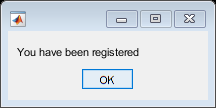

cam=webcam();
preview(cam);
pause(2);
img=snapshot(cam);
pause(2);
closePreview(cam);
folder_image='C:\Users\harsh\Desktop\VFR_image';
baseFileName=sprintf('ImageId #%d.png',eid);
fullFileName=fullfile(folder_image,baseFileName);
imwrite(img,fullFileName);
f1=Face_Features(img);
try
    load database;
    Feature=[Feature;f];
    UserId=[UserId;eid];
    load dbase.mat
    feature1=f1;
    uid=eid;
    save dbase.mat feature1 uid 
catch
    Feature=f;
    UserId=eid;
    save database Feature UserId
    feature1=f1;
    uid=eid;
    save dbase.mat feature1 eid

end
msgbox("You have been registered")